# Ariadna Cortés Danés - Exercici 1 (Parcial 2)

Mètode predictor corrector de Adams-Basforth-Moulton

La funció de distribució normal  s'acostuma a definir mitjançant una integral: 

Φ(x)=12+12π−−√∫x0e−t2/2dt

però també es pot definir com a solució del problema de valors inicials  

        
$$$y\prime (t)=\frac{1}{\sqrt{2\pi }}\cdot e^{-t^2/2},y(0)=1/2$$$


Es demana

1) Construïr una taula de la funció Φ(x) per  x=0.0,0.1,0.2,…,2.9,3.0 resolent el PVI mitjançant el mètode predictor-corrector d' Adams Basforth Moulton. 

% Mètode de  Adams-Basforth
% iniciem per RK4
h = 0.1

h = 0.1000

a = 0; alpha = 1/2;    % y(a) = alpha
b = 3;                % y(b) = ...
t=[a:h:b];
N=length(t);

f = @(t,y) sqrt(1/(2*pi))*exp(-0.5*t.^2);

wrk4  = RK4( f,a,t(4),h,alpha )

wrk4 =     0.5000    0.5398    0.5793    0.6179


w(1) = alpha;
w(2) = wrk4(2);
w(3) = wrk4(3);
w(4) = wrk4(4);


% Predictor Adams-Basforth
for i=4:N-1
    a1 = f(t(i),w(i));
    a2 = f(t(i-1),w(i-1));
    a3 = f(t(i-2),w(i-2));
    a4 = f(t(i-3),w(i-3));
    s = h*(55*a1-59*a2+37*a3-9*a4);
    Y(i+1)= w(i)+s/24;  %predictor adams-basforth
    
    a = f(t(i+1),Y(i+1));   %avaluacio 
    
    S = h*(9*a + 19*a1-5*a2 +a3) ;   % corrector adams-moulton
    w(i+1) = w(i) + S/24;
end

% resultat es [t,w]

2) Calcular l'error local per tal de comparar la solució numèrica aproximada amb la  solució analítica definada mitjançant la funció erf(x)���(�) de Matlab®. La relació entre les dues és $$ \Phi (x)=\frac{1}{2}\left(1-erf\left(-\frac{x}{\sqrt{2}}\right)\right)$$

ySol = 0.5*(1-erf(-t./sqrt(2)))

ySol =     0.5000    0.5398    0.5793    0.6179    0.6554    0.6915    0.7257    0.7580    0.7881    0.8159    0.8413    0.8643    0.8849    0.9032    0.9192    0.9332    0.9452    0.9554    0.9641    0.9713    0.9772    0.9821    0.9861    0.9893    0.9918    0.9938    0.9953    0.9965    0.9974    0.9981    0.9987


error_local = double(abs(w-ySol));
disp(table(t',ySol', w', error_local','VariableNames',{'t','Real','Numeric','E_{local}'}))

     t      Real      Numeric    E_{local} 
    ___    _______    _______    __________

      0        0.5        0.5             0
    0.1    0.53983    0.53983    4.1273e-09
    0.2    0.57926    0.57926    8.0499e-09
    0.3    0.61791    0.61791    1.1578e-08
    0.4    0.65542    0.65542    2.7063e-07
    0.5    0.69146    0.69146    4.8523e-07
    0.6    0.72575    0.72575    6.4654e-07
    0.7    0.75804    0.75804    7.4919e-07
    0.8    0.78814    0.78815    7.9147e-07
    0.9    0.81594    0.81594    7.7526e-07
      1    0.84134    0.84135    7.0568e-07
    1.1    0.86433    0.86433    5.9045e-07
    1.2    0.88493    0.88493    4.3925e-07
    1.3     0.9032     0.9032    2.6283e-07
    1.4    0.91924    0.91924    7.2238e-08
    1.5    0.93319    0.93319    1.2197e-07
    1.6     0.9452     0.9452    3.1031e-07
    1.7    0.95543    0.955

c) Realitzar una gràfica de l'error local per comparar gràficament la solució   aproximada amb la solució analítica Φ(x)Φ(�) definida en l'apartat anterior.

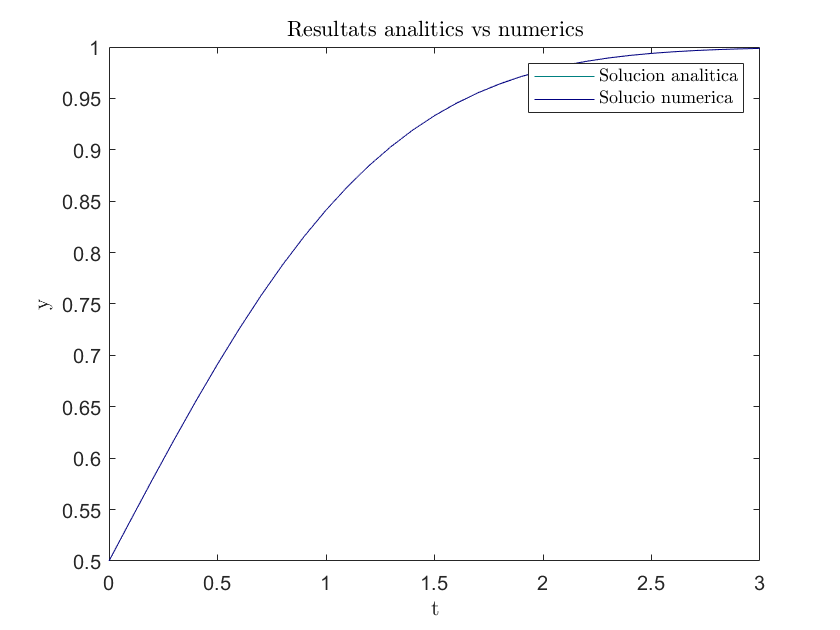

% grafica per comparar graficament dels resultats
plot(t, ySol, 'Color',[0 0.5 0.5])
hold on 
plot(t, w, 'Color',[0 0 0.5])
title('Resultats analitics vs numerics', 'Interpreter',"latex")
legend('Solucion analitica', 'Solucio numerica','interpreter','latex')
xlabel('t','Interpreter',"latex")
ylabel('y','Interpreter',"latex")
hold off

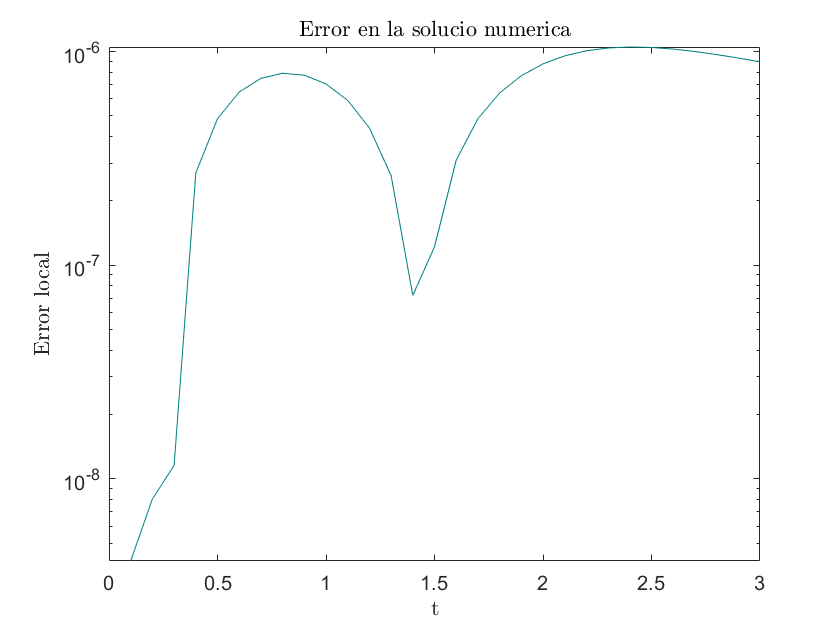


% grafica per a visualitzar l'error
semilogy(t, error_local, 'Color',[0 0.5 0.5])
title('Error en la solucio numerica', 'Interpreter',"latex")
xlabel('t','Interpreter',"latex")
ylabel('Error local','Interpreter',"latex")

d) Argumenta i raona la concordança dels teus resultats amb l'ordre del mètode numèric emprat.

% Per a raonar sobre l'ordre del metode hauriem de fer diverses execucions
% amb valors de h diferents, per a poder veure el creixement o decreixement
% relatiu de l'error. El que podem veure d'aquesta gràfica és un error molt
% estable, és a dir, l'error local no s'incrementa a mida que avancem en el
% mètode (cal remarcar que al principi l'error creix, també degut a que
% comencem amb 4 valors de RK4, que ja no corresponen a la solució exacta).
% Aquests resultats de l'error mostren la convergència del mètode.